Ts = 0.01;
Kp_new = Kp*100;
Ti = Kp_new / Ki;
Td = Kd / Kp_new;
r0 = Kp_new * (1 + Ts / (2 * Ti) + Td / Ts);
r1 = Kp_new * (Ts / (2 * Ti) - 2 * Td / Ts - 1);
r2 = Kp_new * Td / Ts;

W = a4 + a3*Ts + a2*Ts^2 + a1*Ts^3;
P1 = 3*a4 + 2*a3*Ts + a2*Ts^2;
P2 = -(3*a4 + a3*Ts);
P3 = a4;
Q0 = b2*Ts^2 + b1*Ts^3;
Q1 = -b2*Ts^2;

fprintf('--- Współczynniki Równania Obiektu ---\n');

--- Współczynniki Równania Obiektu ---


fprintf('W = %.4f, P1 = %.4f, Q0 = %.4f\n', W, P1, Q0);

W = 0.0359, P1 = 0.1064, Q0 = -0.0006



fprintf('\n--- Współczynniki Regulatora Cyfrowego ---\n');


--- Współczynniki Regulatora Cyfrowego ---


fprintf('r0 = %.4f\n', r0);

r0 = -69.5233


fprintf('r1 = %.4f\n', r1);

r1 = 110.8459


fprintf('r2 = %.4f\n', r2);

r2 = -41.3231


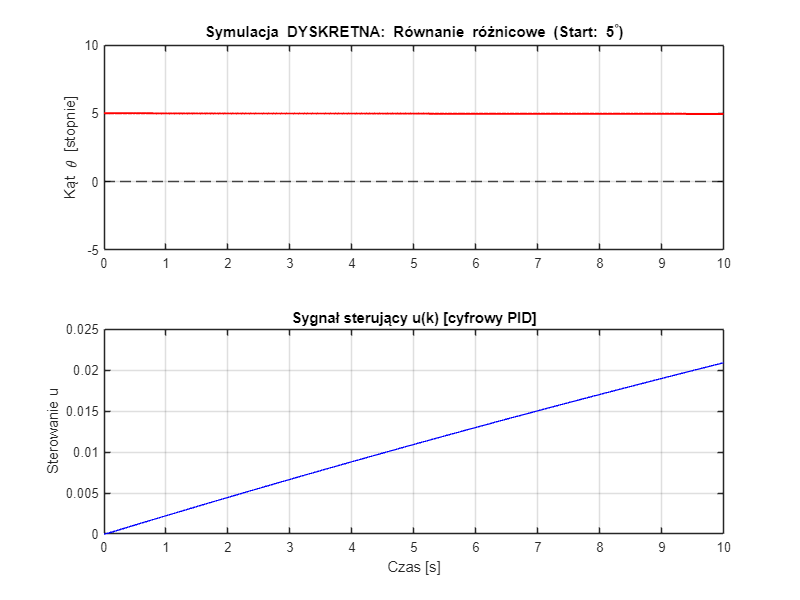


T_sim = 10; % Czas symulacji [s]
N = T_sim / Ts; % Liczba próbek

% Inicjalizacja wektorów
y = zeros(1, N); % Wyjście (kąt)
u = zeros(1, N); % Sterowanie
e = zeros(1, N); % Uchyb

% WARUNEK POCZĄTKOWY: 5 stopni
start_angle_deg = 5;
start_angle_rad = deg2rad(start_angle_deg);

y(1:4) = start_angle_rad; 
e(1:4) = 0 - y(1:4); 
u(1:4) = 0;
yzad = 0;

for k = 4:N
    % A. Pomiar i obliczenie uchybu
    % W rzeczywistości mierzymy y(k-1) i liczymy sterowanie na chwilę k
    e(k) = yzad - y(k-1); 
    
    % B. Obliczenie sterowania (Równanie różnicowe PID)
    % u(k) = u(k-1) + r0*e(k) + r1*e(k-1) + r2*e(k-2)
    u(k) = u(k-1) + r0*e(k) + r1*e(k-1) + r2*e(k-2);
    
    % (Opcjonalnie) Ograniczenie napięcia silnika (Saturacja)
%     if u(k) > 12, u(k) = 12; elseif u(k) < -12, u(k) = -12; end
    
    % C. Obliczenie wyjścia obiektu (Równanie różnicowe Obiektu)
    % Twoje wzór: y(k) = 1/W * (suma P... + suma Q...)
    y(k) = (1/W) * ( P1*y(k-1) + P2*y(k-2) + P3*y(k-3) + Q0*u(k) + Q1*u(k-1) );
end

t_vec = 0:Ts:(N-1)*Ts;

figure('Position', [100, 100, 800, 600]);

subplot(2,1,1);
plot(t_vec, rad2deg(y), 'r-', 'LineWidth', 1.5);
grid on;
title(['Symulacja DYSKRETNA: Równanie różnicowe (Start: ' num2str(start_angle_deg) '^\circ)']);
ylabel('Kąt \theta [stopnie]');
yline(0, 'k--');
% xlim([0, 2]); % Zoom na początek
ylim([-5, 10]);

subplot(2,1,2);
stairs(t_vec, u, 'b-', 'LineWidth', 1); % Stairs bo to sygnał cyfrowy
grid on;
title('Sygnał sterujący u(k) [cyfrowy PID]');
ylabel('Sterowanie u');
xlabel('Czas [s]');

% xlim([0, 2]);
% ylim([-12, 12]);